## In-Rush Current Analysis of VBUS Capacitors

[Source](https://www.electronicdesign.com/technologies/power/article/21196349/how-do-you-choose-the-right-type-of-ntc-thermistor-to-limit-inrush-current-for-capacitive-applications)

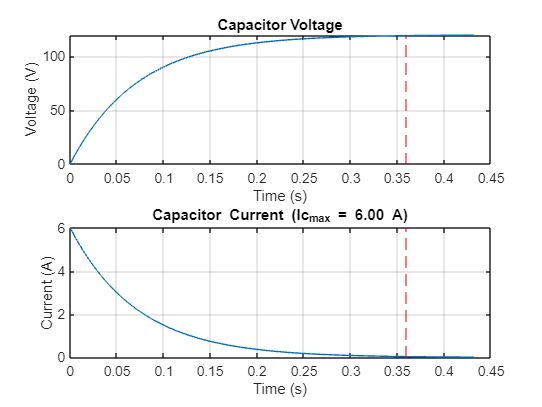


n = 100;    % Oversampling rate

Vin = 120;  % Mains voltage, 120 VAC (rms)
Vpk = Vin*sqrt(2);

% Series resistance of bus capacitor bank
R_in = 20;%HVBUS.ESR_cap;

tau = R_in * HVBUS.Cap;
t_f = 6*tau;

% Compute sampling rate given time constant
fs = (1/tau)*n;
ts = 1/fs;
t = 0:ts:t_f;
V0 = Vin;               % Initial capacitor voltage

% Compute Vbus capacitor V/I charge curves
v_c = V0*(1-exp(-t./tau));
i_c = (V0/R_in)*exp(-t./tau);
i_c_max = max(i_c);


% Plot capacitor V/I chage curves
subplot(2,1,1);
plot(t,v_c);
grid on;
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Capacitor Voltage');
xline(5*tau,'r--');

subplot(2,1,2);
plot(t,i_c);
grid on;
xlabel('Time (s)');
ylabel('Current (A)');
title(sprintf('Capacitor Current (Ic_max = %0.2f A)',i_c_max));
xline(5*tau,'r--');

## Bus Capacitance Safe Discharge Performance

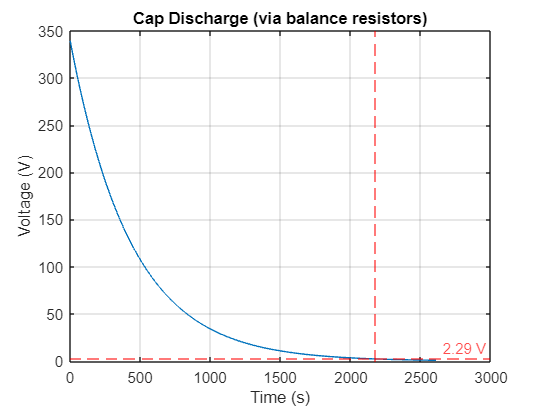


% Resistance is series combination of balance resistors
tau = 2 * HVBUS.R_balance * HVBUS.Cap;
t_f = 6*tau;

% Compute sampling rate given time constant
fs = (1/tau)*n;
ts = 1/fs;
t = 0:ts:t_f;

% Generate voltage discharge curve
V0 = HVBUS.Vbus;            
v_c_discharge = V0*exp(-t/tau);

figure();
plot(t,v_c_discharge);
grid on;
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Cap Discharge (via balance resistors)');
xline(5*tau,'r--');         % Plot vertical line at t=5*tau
% Plot horizonal line at v_c(5*tau)
y_val = V0*exp(-5); 
yline(y_val,'r--',sprintf("%0.2f V",y_val));


% Compute discharge time for decaying to less than 1% of Vbus through
% balance resistors
HVBUS.SafeDischargeTime_balance = 5*tau;    % sec


### Compute discharge curves for capacitor bank with bleed resistor

T_safe_discharge_tgt = 10;      % Desired time to reach 99.3% of capacitor discharged, sec
%C = HVBUS.Cap_eq;   % legacy
C = HVBUS.Cap;      % test
tau = T_safe_discharge_tgt/5;
R_bleed_nom = tau/C;
R_bleed = round63(R_bleed_nom, 'E96', 'down');
fprintf("HV Bus bleed resistor: %0.2f kOhm\n\n", R_bleed/1e3);

HV Bus bleed resistor: 1.10 kOhm



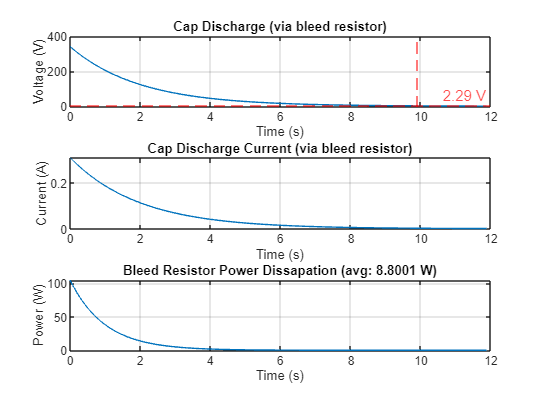


% Bleed resistor
%R_bleed = 1e3;  % Ohm

% Time constant
tau = R_bleed * C;
t_f = 6*tau;

% Compute sampling rate given time constant
fs = (1/tau)*n;
ts = 1/fs;
t = 0:ts:t_f;

% Generate voltage discharge curve
V0 = HVBUS.Vbus;            
v_c_bleed_discharge = V0*exp(-t/tau);       % v(t)
i_c_bleed_discharge = (V0/R_bleed)*exp(-t/tau); % i(t)
i_c_bleed_discharge_avg = mean(i_c_bleed_discharge);

% Compute power dissapation curve of bleed resistor
P_dis_bleed = (i_c_bleed_discharge.^2) * R_bleed;    % P(t)
% Compute the average power dissipation
P_dis_bleed_avg = mean(P_dis_bleed);
%P_dis_bleed_rms = rms(P_dis_bleed);

subplot(3,1,1);
plot(t,v_c_bleed_discharge);
grid on;
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Cap Discharge (via bleed resistor)');
xline(5*tau,'r--');         % Plot vertical line at t=5*tau
% Plot horizonal line at v_c(5*tau)
y_val = V0*exp(-5); 
yline(y_val,'r--',sprintf("%0.2f V",y_val));

subplot(3,1,2);
plot(t,i_c_bleed_discharge);
grid on;
xlabel('Time (s)');
ylabel('Current (A)');
title(sprintf('Cap Discharge Current (avg: %0.4f A)',i_c_bleed_discharge_avg));


subplot(3,1,3);
plot(t,P_dis_bleed);
grid on;
xlabel('Time (s)');
ylabel('Power (W)');
title(sprintf('Bleed Resistor Power Dissipation (avg: %0.4f W)', P_dis_bleed_avg));

%xline(5*tau,'r--');         % Plot vertical line at t=5*tau
% Plot horizonal line at v_c(5*tau)
%y_val = V0*exp(-5); 
%yline(y_val,'r--',sprintf("%0.2f V",y_val));